# Zhoubao Pang

# Midterm Project Extra Credit

# Applied Linear Control

# Spring 2019

clc;clear;
close all

## Section 1

Sample rate  from the midterm assignment sheet.

Fs = 20; % (Hz)
Fnyq = Fs/2;

Calculate the sample period.

Ts = 1/Fs; % (s)

Reduced number of samples

N = 2^11; 

Calcualte freqeuncy resolution

F = Fs / N; % (Hz)

Calcualte the total time period of the data

T = N * Ts; % (s)

Inform how long the it will take to collect the number of samples

fprintf("The data would take %d minutes to collect\n\r",T/60)

The data would take 1.706667e+00 minutes to collect



Create time vector.

t = Ts * [0:N-1]; % (s)

Create bandpass filter with cutoff frequency of 0.03 Hz and 8 Hz. 

[b1,a1] = butter(2,[0.03 8]/(Fs/2)); 

Create filtered white noise input as the input signals.

u1 = filter(b1,a1,2.6*randn(1,N));
u2 = filter(b1,a1,2.6*randn(1,N));

 Create zero input

u0 = zeros(1,N); 

Plot frequency spectrum and time domain plots for the input signal. The excitation does not saturate the DAC more than  0.1%

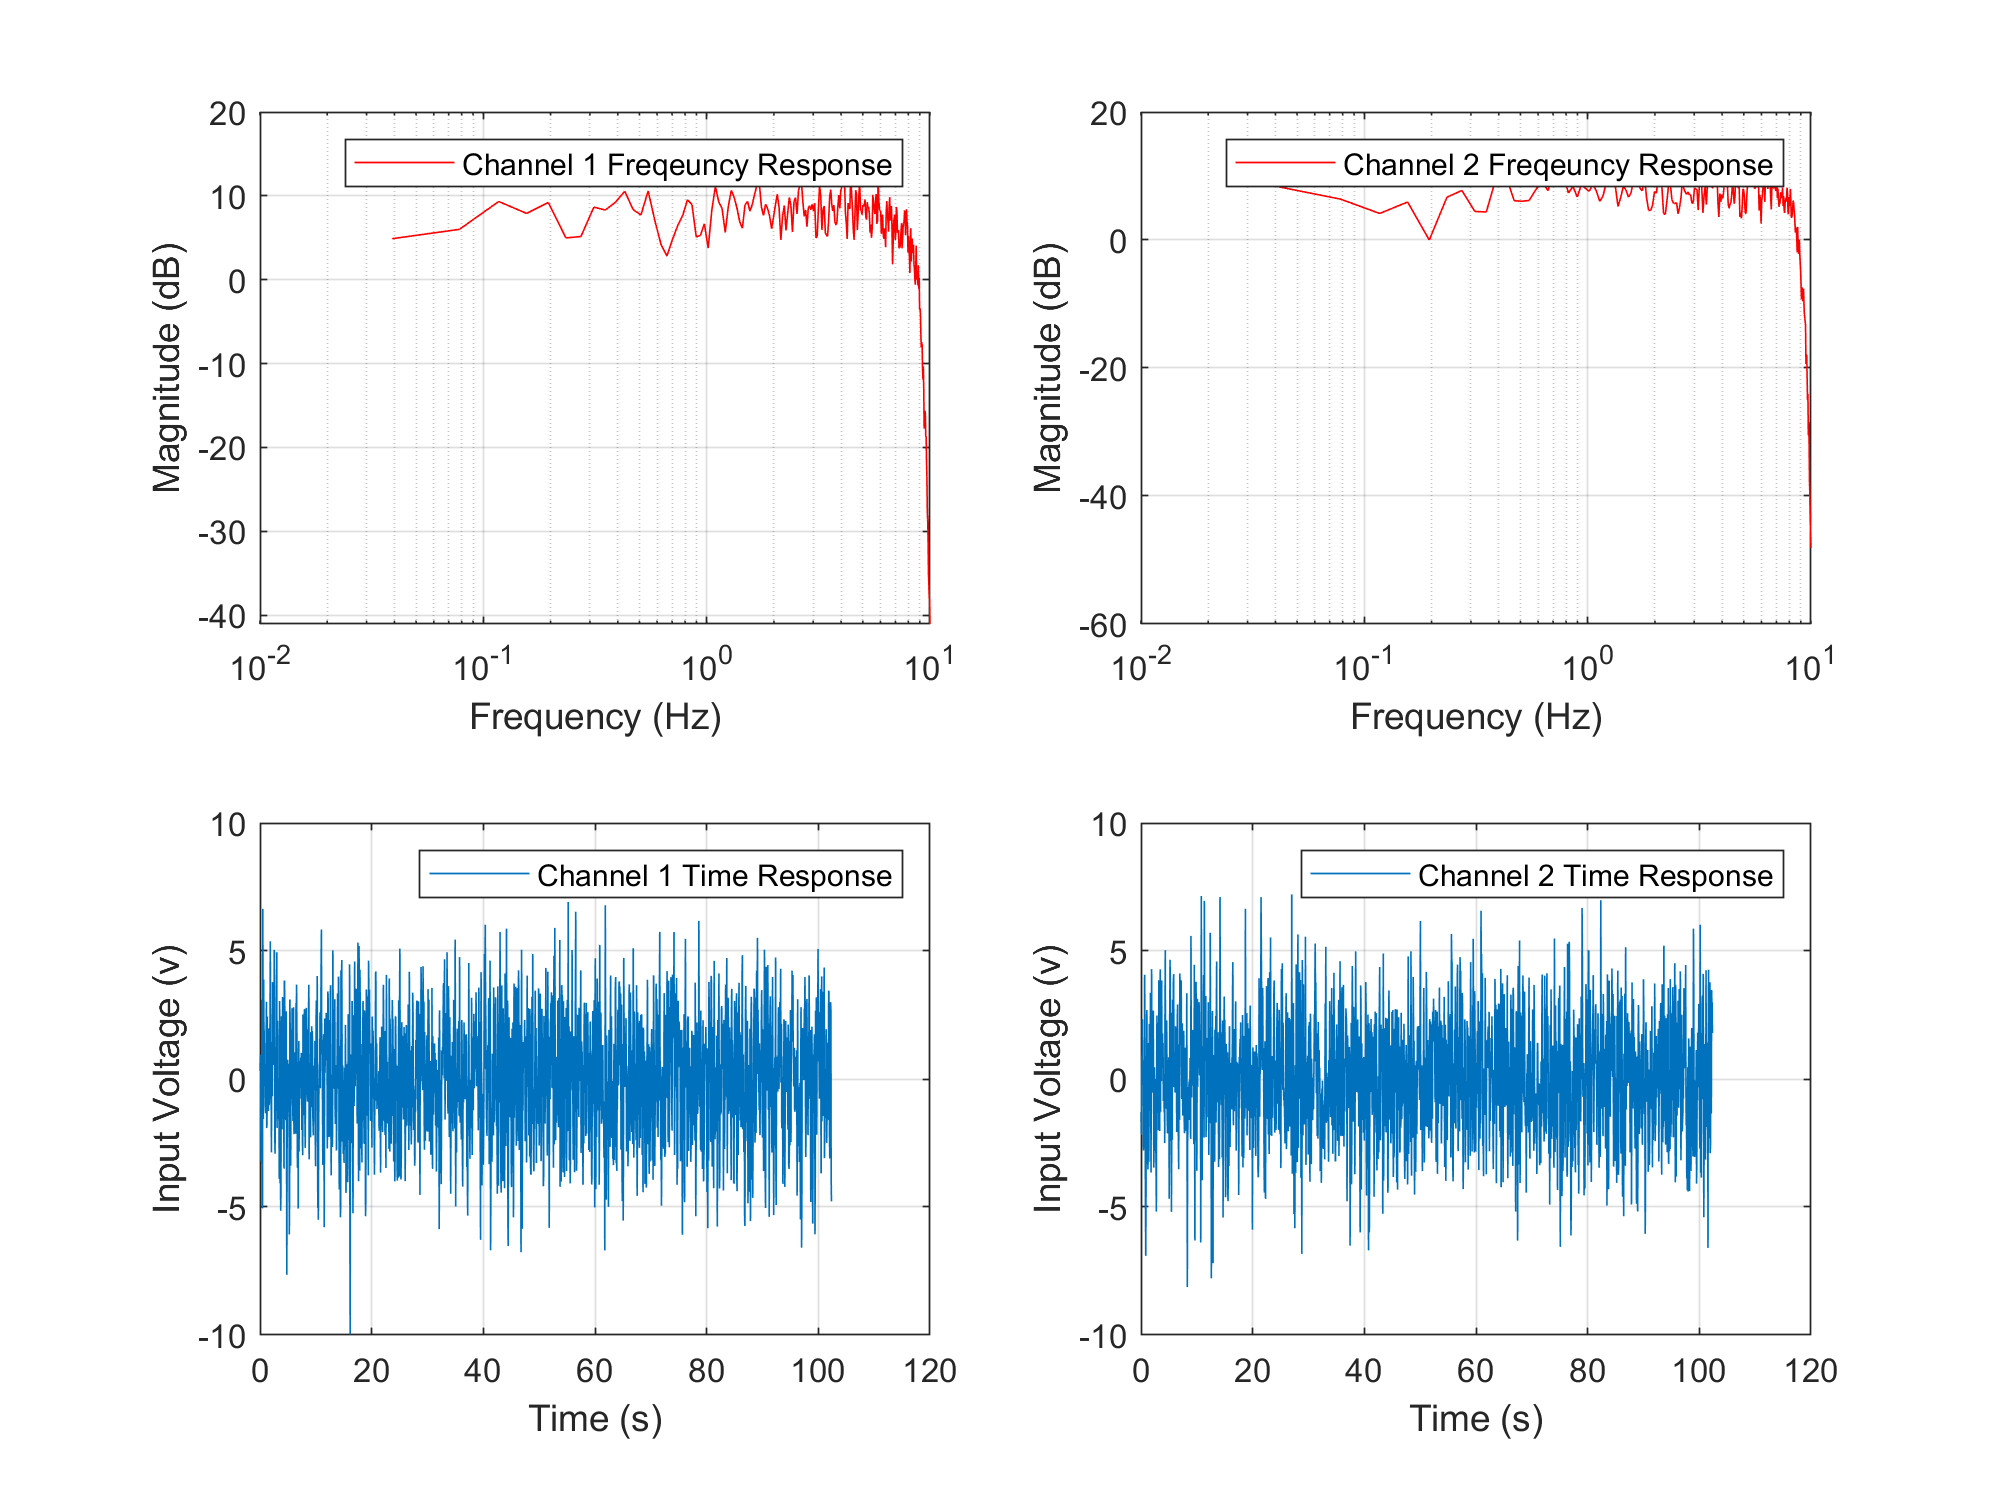

figure 
set(gca,'fontsize',14) 
set(gcf,'Position',[0 0 800 600])
subplot(2,2,1)
nfft = 2^9;
wndo = nfft;
ovlp = nfft/2;
[Pxx,FR] = cpsd(u1,u1,wndo,ovlp,nfft,Fs);
semilogx(FR,10*log10(Pxx*Fs/2),'r')
xlim([0.01 Fs/2])
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
legend('Channel 1 Freqeuncy Response')
grid on
subplot(2,2,3)
plot(t,u1)
xlabel('Time (s)')
ylabel('Input Voltage (v)')
legend('Channel 1 Time Response')
grid on

subplot(2,2,2)
wndo = nfft;
ovlp = nfft/2;
[Pxx,FR] = cpsd(u2,u2,wndo,ovlp,nfft,Fs);
semilogx(FR,10*log10(Pxx*Fs/2),'r')
xlim([0.01 Fs/2])
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
legend('Channel 2 Freqeuncy Response')
grid on
subplot(2,2,4)
plot(t,u2)
xlabel('Time (s)')
ylabel('Input Voltage (v)')
legend('Channel 2 Time Response')
grid on

## Section 2

u10 only excite the first channel and gives zero input to the other channel.

u10= [u1;u0];
y1 = s19_plant(u10);

*** Warning *** s19_plant.p has only been tested on:
    R2017a, R2017b, R2018a, and R2018b


u01 only excite the second channel and gives zero input to the other channel.

u01= [u0;u2];
y2 = s19_plant(u01);

*** Warning *** s19_plant.p has only been tested on:
    R2017a, R2017b, R2018a, and R2018b


u01 provides zero input to both channels.

u00= [u0;u0];
yn = s19_plant(u00);

*** Warning *** s19_plant.p has only been tested on:
    R2017a, R2017b, R2018a, and R2018b


Calculate signal to noise ratio(SNR) of 4 paths in dB

SNR_dB(1,1) = 10*log10((std(y1(1,:))^2 - std(yn(1,:))^2) / std(yn(1,:))^2); %dB
SNR_dB(1,2) = 10*log10((std(y2(1,:))^2 - std(yn(1,:))^2) / std(yn(1,:))^2); %dB 
SNR_dB(2,1) = 10*log10((std(y1(2,:))^2 - std(yn(2,:))^2) / std(yn(2,:))^2); %dB
SNR_dB(2,2) = 10*log10((std(y2(2,:))^2 - std(yn(2,:))^2) / std(yn(2,:))^2); %dB

display(SNR_dB)

SNR_dB =    43.5096   37.6689
   34.0010   38.5182


## Section 3

Power Spectrum of noise.

[Pxxn1,FR] = pwelch(yn(1,:),wndo,ovlp,nfft,Fs);
[Pxxn2,~] = pwelch(yn(2,:),wndo,ovlp,nfft,Fs);

Power Spectrum of of the 4-path outputs.

[Pxx11,~] = pwelch(y1(1,:),wndo,ovlp,nfft,Fs);
[Pxx12,~] = pwelch(y2(1,:),wndo,ovlp,nfft,Fs);
[Pxx21,~] = pwelch(y1(2,:),wndo,ovlp,nfft,Fs);
[Pxx22,~] = pwelch(y2(2,:),wndo,ovlp,nfft,Fs);

Plot power spectrum and respective time domain outputs.

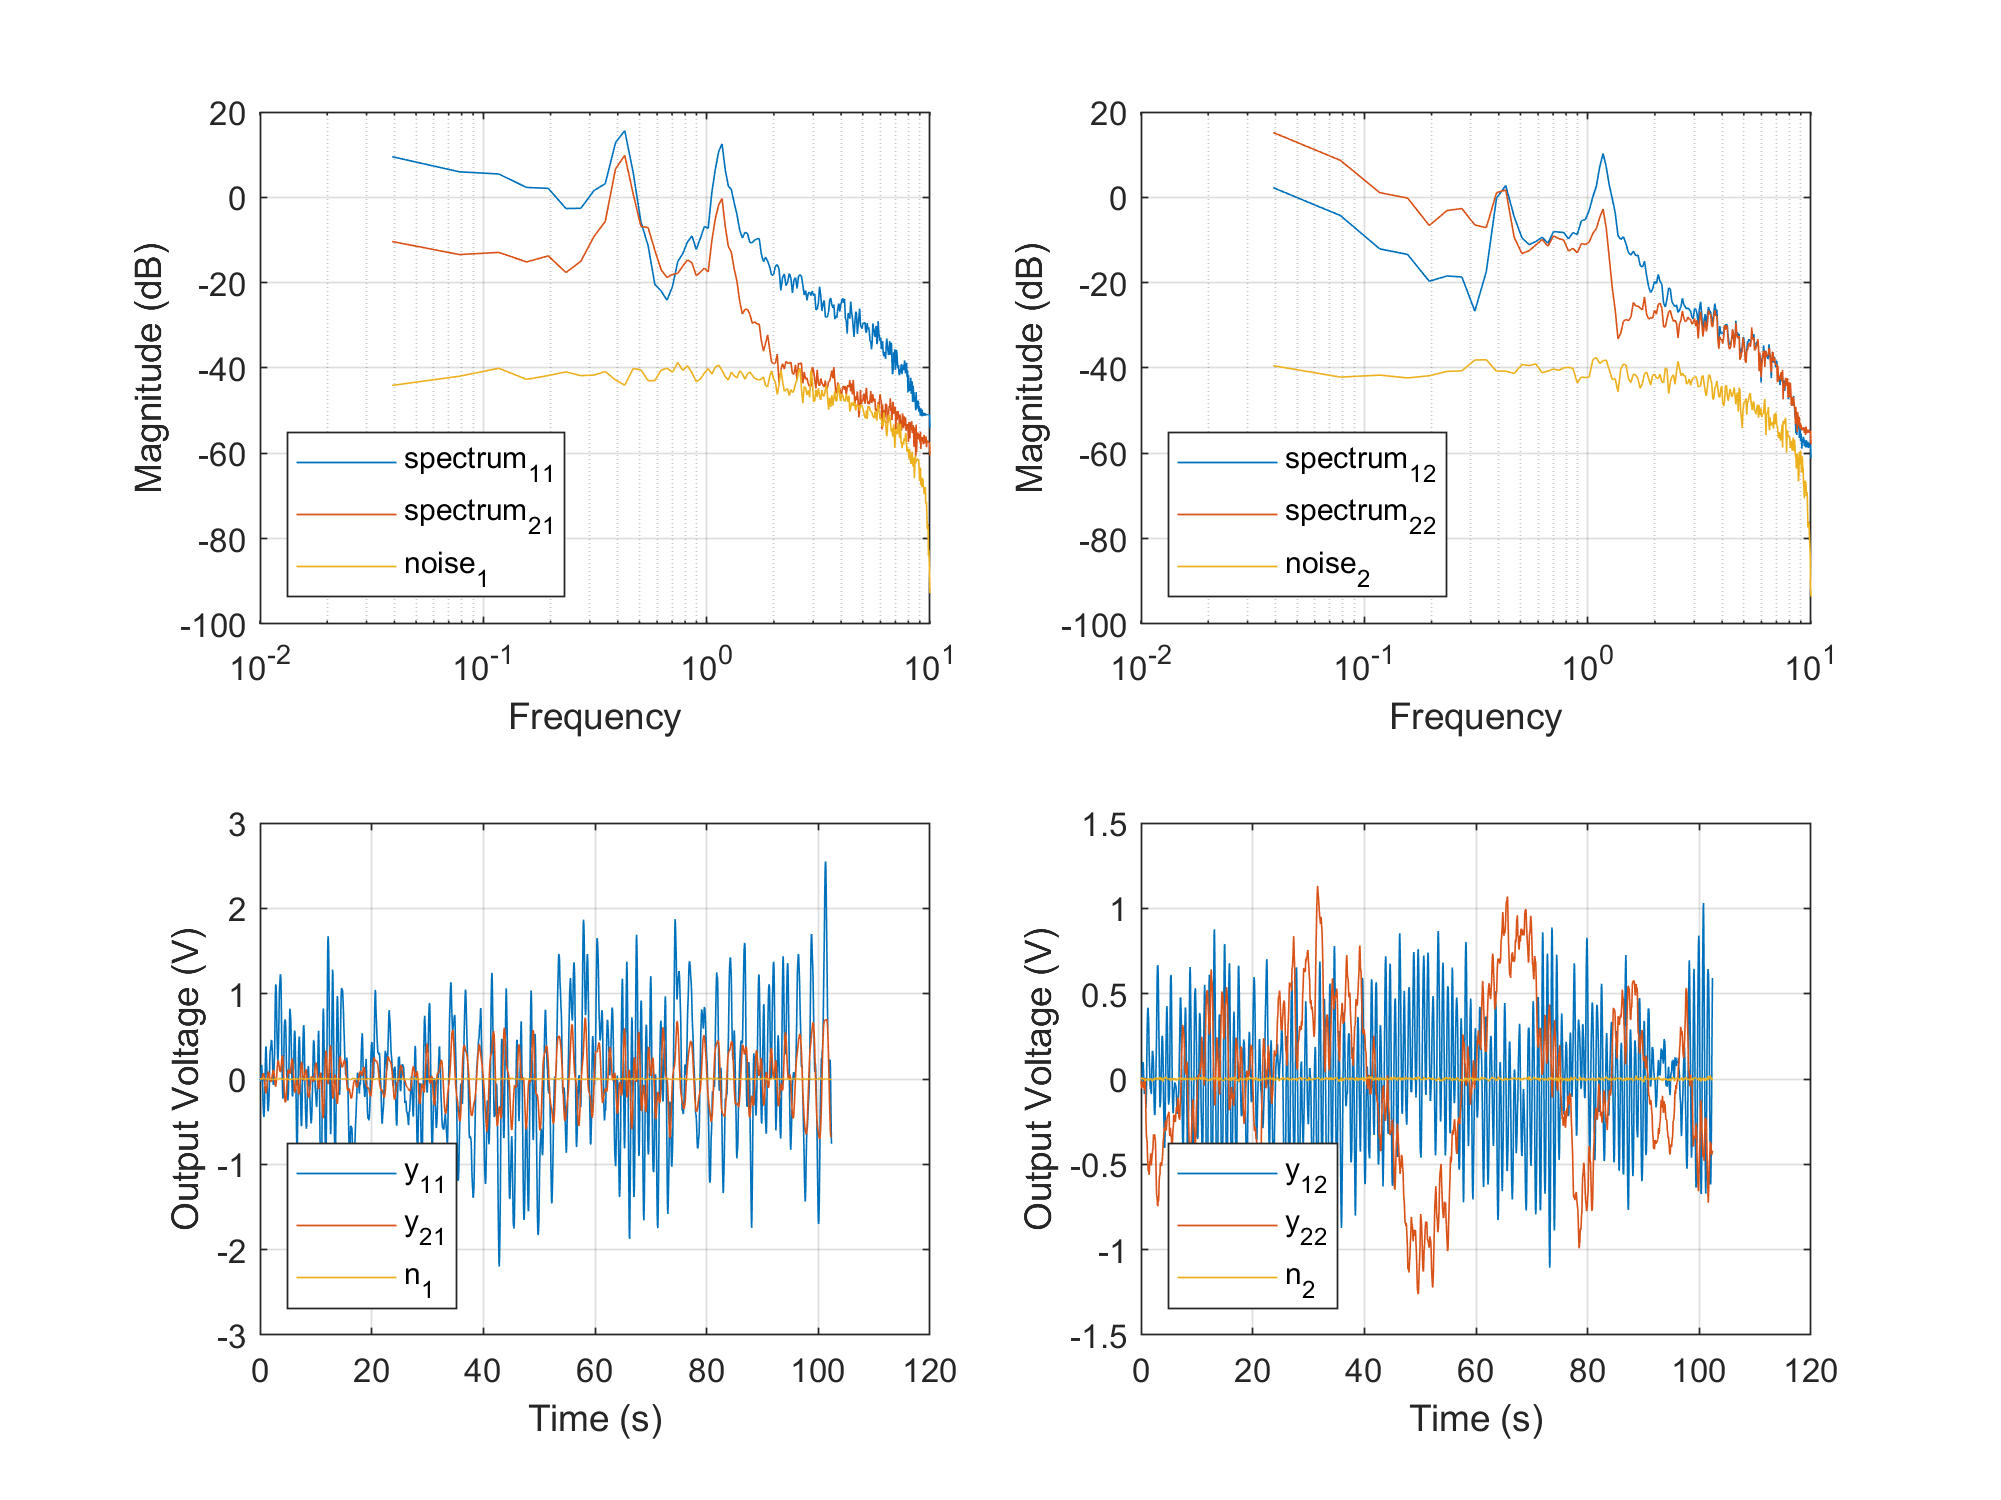

figure
set(gca,'fontsize',14) 
set(gcf,'Position',[0 0 800 600])
subplot(2,2,1)
semilogx(FR,10*log10(Pxx11*Fs/2))
hold on
semilogx(FR,10*log10(Pxx21*Fs/2))
semilogx(FR,10*log10(Pxxn1*Fs/2))
xlim([0.01 Fs/2])
xlabel('Frequency')
ylabel('Magnitude (dB)')
grid on
legend('spectrum_1_1','spectrum_2_1','noise_1','Location','southwest')
hold off

subplot(2,2,2)
semilogx(FR,10*log10(Pxx12*Fs/2))
hold on
semilogx(FR,10*log10(Pxx22*Fs/2))
semilogx(FR,10*log10(Pxxn2*Fs/2))
xlim([0.01 Fs/2])
xlabel('Frequency')
ylabel('Magnitude (dB)')
grid on
legend('spectrum_1_2','spectrum_2_2','noise_2','Location','southwest')
hold off

subplot(2,2,3)
plot(t,y1(1,:),t,y1(2,:),t,yn(1,:))
legend('y_1_1','y_2_1','n_1','Location','southwest')
ylabel('Output Voltage (V)')
xlabel('Time (s)')
grid on

subplot(2,2,4)
plot(t,y2(1,:),t,y2(2,:),t,yn(2,:))
legend('y_1_2','y_2_2','n_2','Location','southwest')
ylabel('Output Voltage (V)')
xlabel('Time (s)')
grid on

## Section 4

Calculate H1 of 4 signal paths.

[H1(1,1,:),fr] = tfestimate(u1,y1(1,:),wndo,ovlp,nfft,Fs);
[H1(1,2,:),~] = tfestimate(u2,y2(1,:),wndo,ovlp,nfft,Fs);
[H1(2,1,:),~] = tfestimate(u1,y1(2,:),wndo,ovlp,nfft,Fs);
[H1(2,2,:),~] = tfestimate(u2,y2(2,:),wndo,ovlp,nfft,Fs);

Calculate the coherence of the 4 paths.

gamma(1,1,:) = mscohere(u1,y1(1,:),wndo,ovlp,nfft,Fs);
gamma(1,2,:) = mscohere(u2,y2(1,:),wndo,ovlp,nfft,Fs);
gamma(2,1,:) = mscohere(u1,y1(2,:),wndo,ovlp,nfft,Fs);
gamma(2,2,:) = mscohere(u2,y2(2,:),wndo,ovlp,nfft,Fs);

## Section 5

Select the number of zeros.

Nb = [4 5;...
      5 5];

Select the number of poles.

Na = 5; 

Select weighting vector for invfreqz to be one from 0.1 Hz to 3 Hz.

wt = zeros(length(fr),1);
wt(2:50) = 1;

select infreqz iteration number

iter = 1E6;

Calcualte the transfer function of each signal path.

for m = 1:2
    for p = 1:2
        [num, den] = invfreqz(squeeze(H1(p,m,:)),(pi*fr)/(Fs/2),Nb(p,m),Na,wt,iter);
        NUM{p,m,:} = num;
        DEN{p,m,:} = den;
    end
end

Create transfer function model

Htf = tf(NUM,DEN,Ts); 

Apply minimal realization transformation or pole zero cancellation.

Hmr = minreal(Htf);

## Section 6

Form state-space realization

Hss = ss(Hmr); 

Aquire Balanced realization model and get the hankel singular value

[Hbr, Hsv] = balreal(Hss); % [balance realization, hankel singular values]

Get the number of states from the balanced realization model

NFIT = size(Hbr.A,1); % extract number of rows of A matrix

Plot the states' hankel singular values in bar chart.

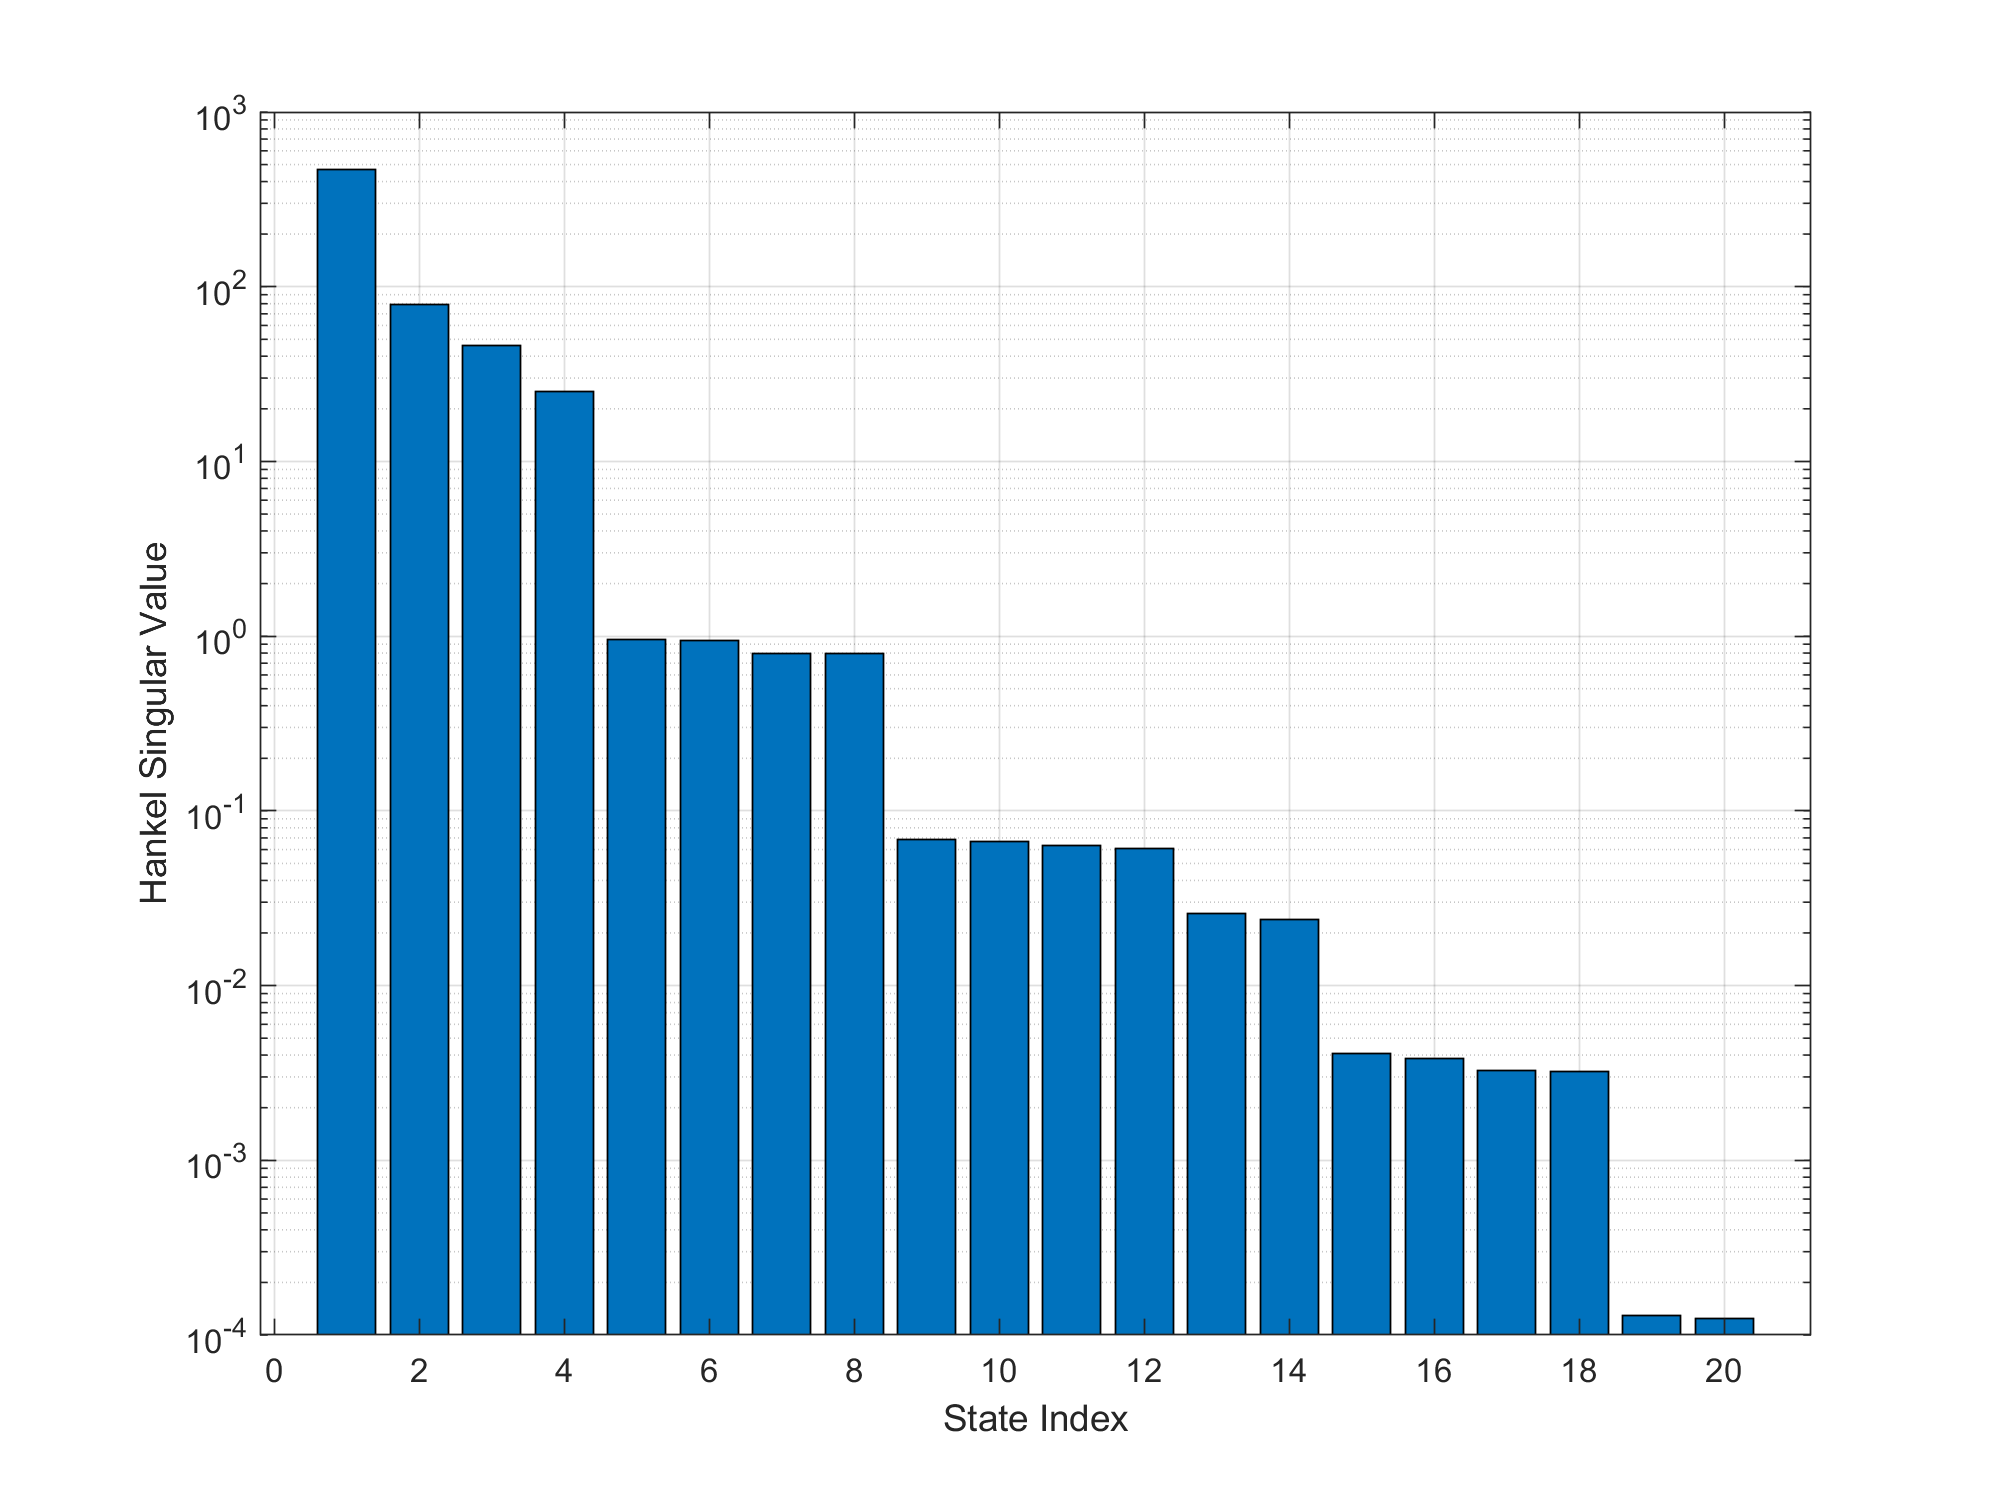

figure
set(gca,'fontsize',14) 
set(gcf,'Position',[0 0 800 600])
bar([1:NFIT],Hsv)
grid on
set(gca,'yscale','log')
ylabel('Hankel Singular Value')
xlabel('State Index')

From the bar chart, we can see a huge difference between state 7 and state 7. Therefore, the cutoff threshold is chosen to be 0.1.

HSV_cutoff = 0.1;  % based on visual inspection of the bar chart
elim = (Hsv < HSV_cutoff);    % Boolean vector (true=eliminate) 

Applied state model reduction from the balanced realization state space model.

Hss_red = modred(Hbr, elim, 'Truncate'); 

## Section 7

Poles = pole(Hss_red);
[Wn, Zeta] = damp(Hss_red);
Natural_Frequency_Hz = Wn / (2*pi);
T = table(Poles,Natural_Frequency_Hz,Zeta);

Show the remaining poles and its natural frequency and damping coefficient after the model reduction

disp(T)

         Poles          Natural_Frequency_Hz      Zeta  
    ________________    ____________________    ________

    0.92363+0.35391i         1.8971e-05                1
    0.92363-0.35391i         7.5619e-05                1
    0.98437+0.13558i         0.00056881                1
    0.98437-0.13558i         0.00072378                1
    0.99982+0i                  0.43613         0.046383
    0.99977+0i                  0.43613         0.046383
    0.99999+0i                   1.1653         0.029899
    0.99998+0i                   1.1653         0.029899



## Section 8

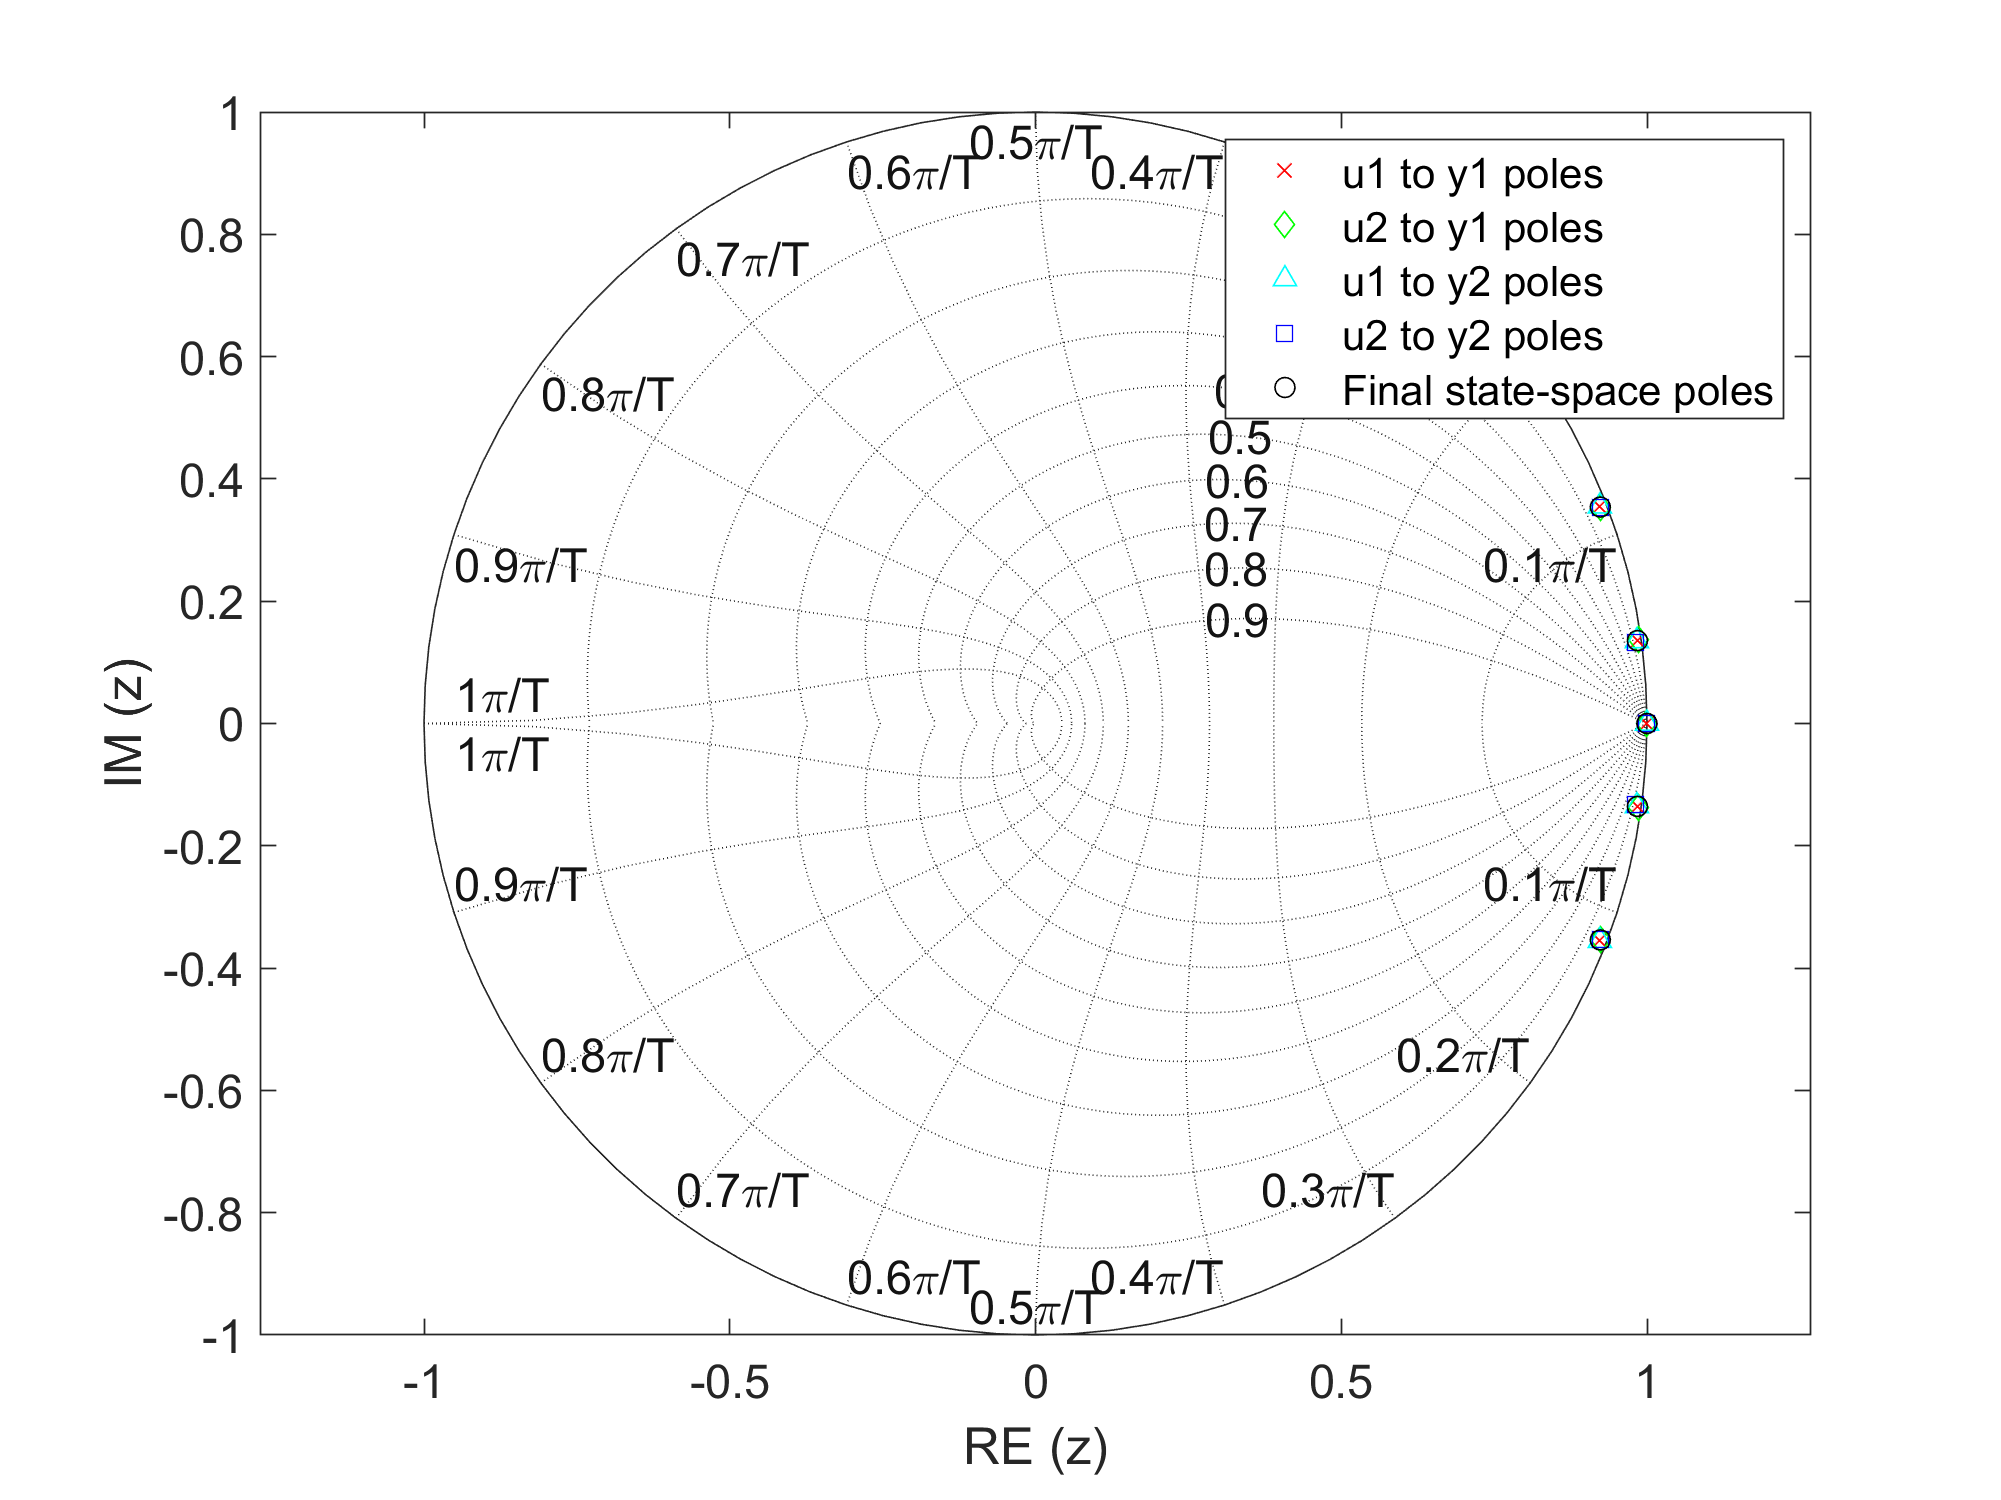


figure
set(gca,'fontsize',14) 
set(gcf,'Position',[0 0 800 600])
hold on
plot(pole(Htf(1,1)),'x','Color','r')
plot(pole(Htf(1,2)),'d','Color','g')
plot(pole(Htf(2,1)),'^','Color','c')
plot(pole(Htf(2,2)),'s','Color','b')

plot(pole(Hss_red),'o','Color','k')
hold off
legend('u1 to y1 poles','u2 to y1 poles','u1 to y2 poles','u2 to y2 poles',...
       'Final state-space poles','AutoUpdate','off')
zgrid
axis equal
xlabel('RE (z)')
ylabel('IM (z)')

## Section 9

Calculate the phase and magnitude of the original transfer function.

FreqResp_tf = squeeze(freqresp(Htf,2*pi*fr)); 
Ph_tf = (180/pi)*angle(FreqResp_tf);
Mag_tf = 20*log10(abs(FreqResp_tf));

Calculate the phase and magnitude of the final state space model.

FreqResp_red = squeeze(freqresp(Hss_red,2*pi*fr)); 
Ph_red = (180/pi)*angle(FreqResp_red);
Mag_red = 20*log10(abs(FreqResp_red));

## Section 10

Create 4-path bode plot with coherence.

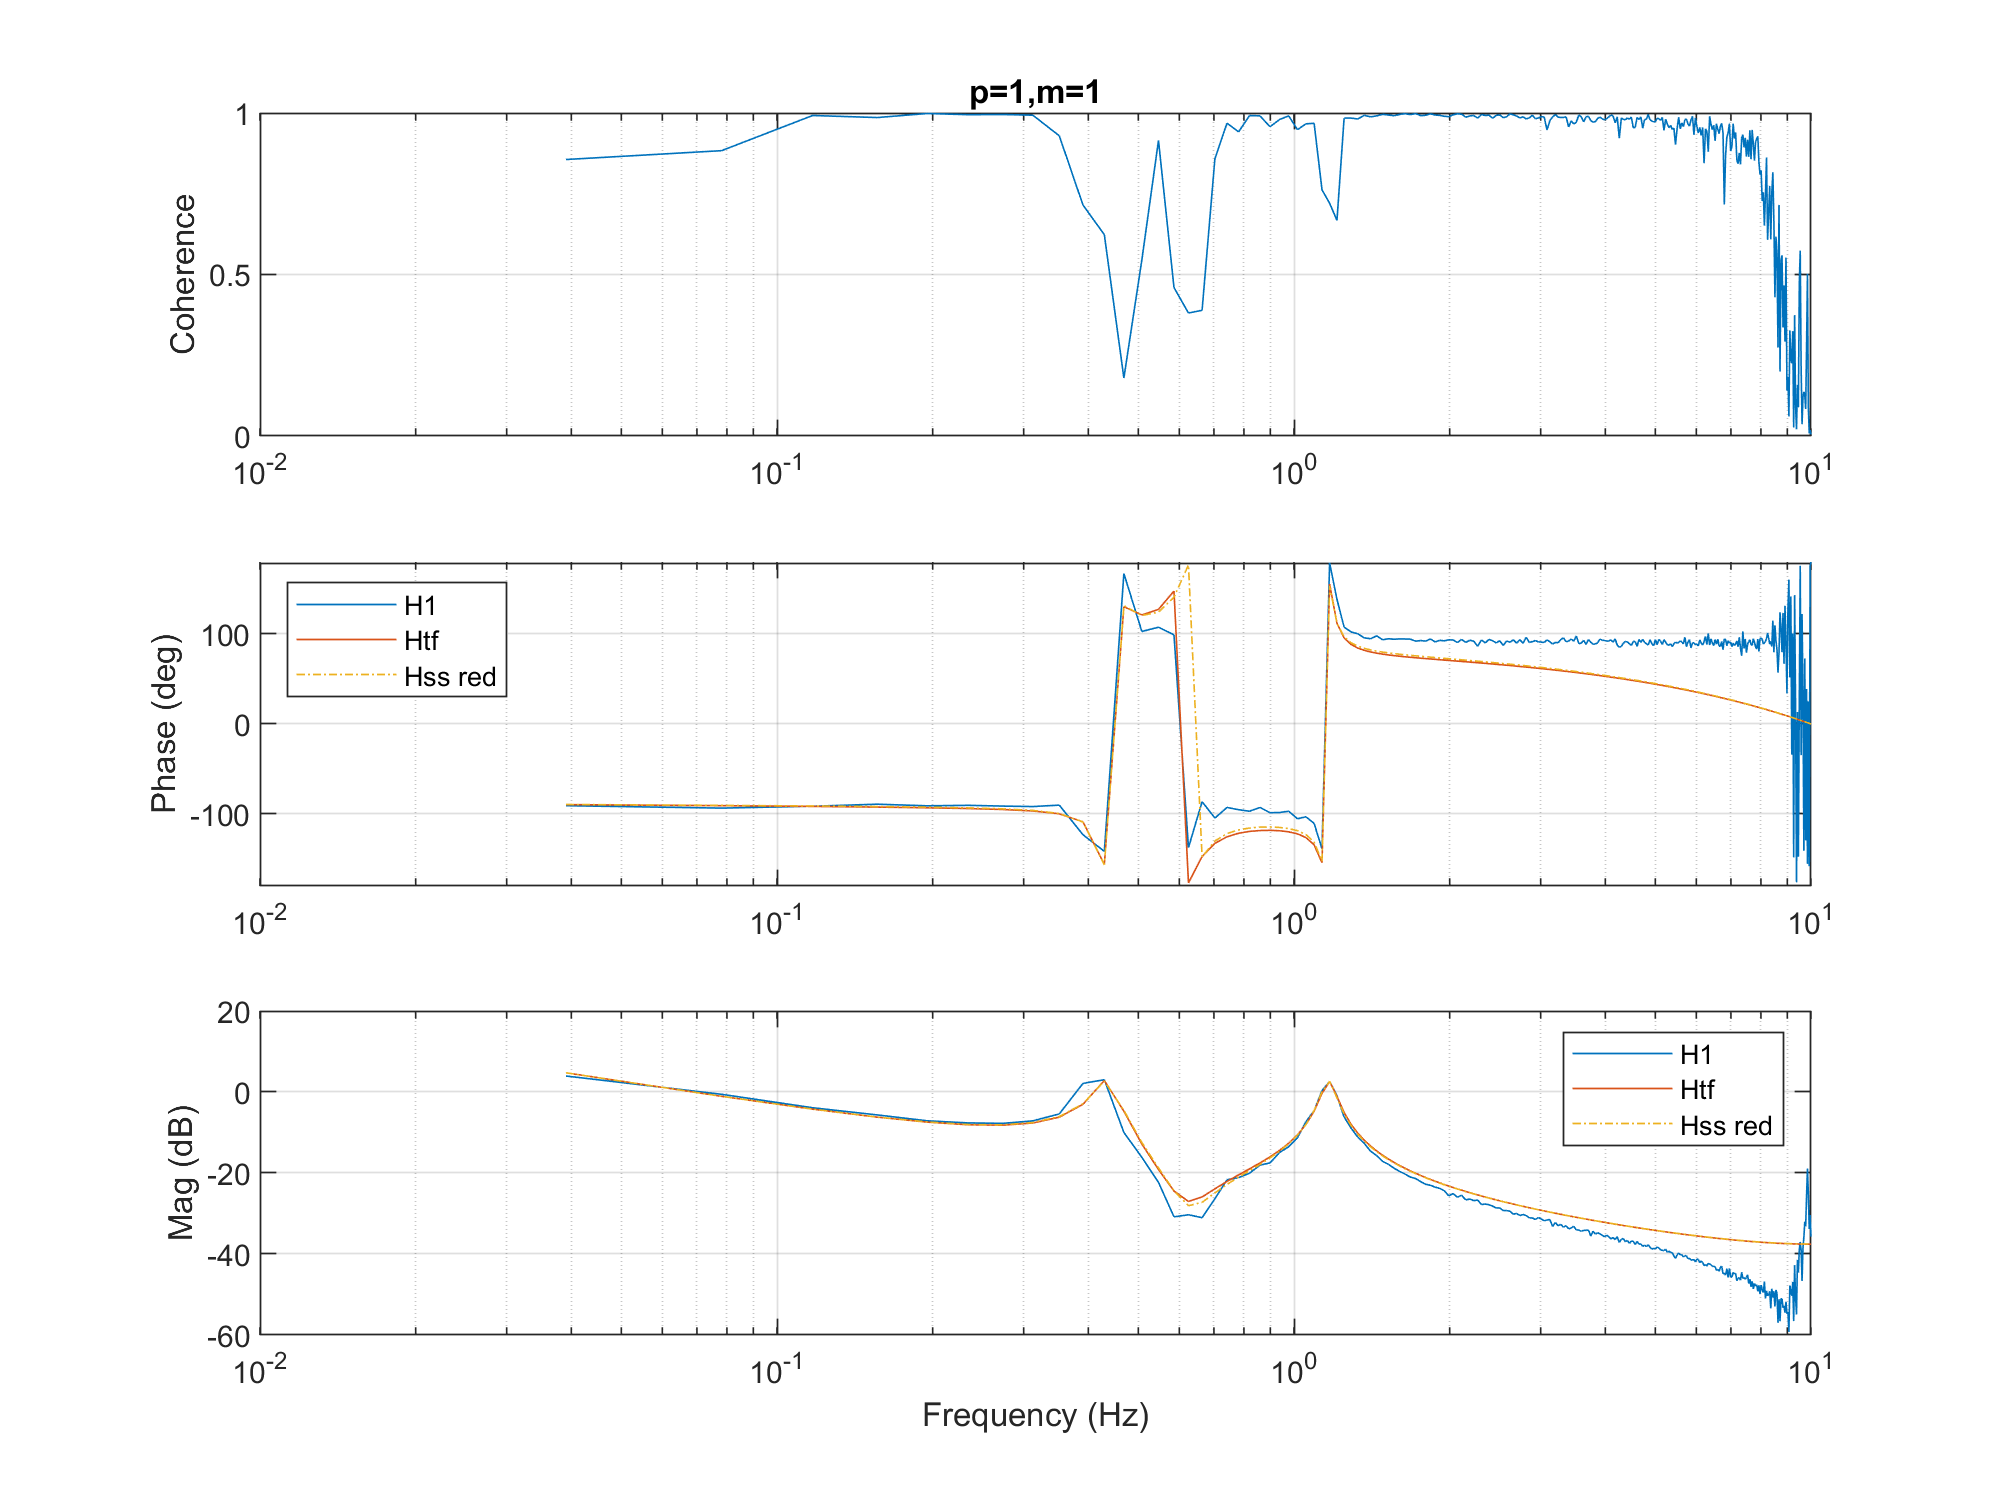

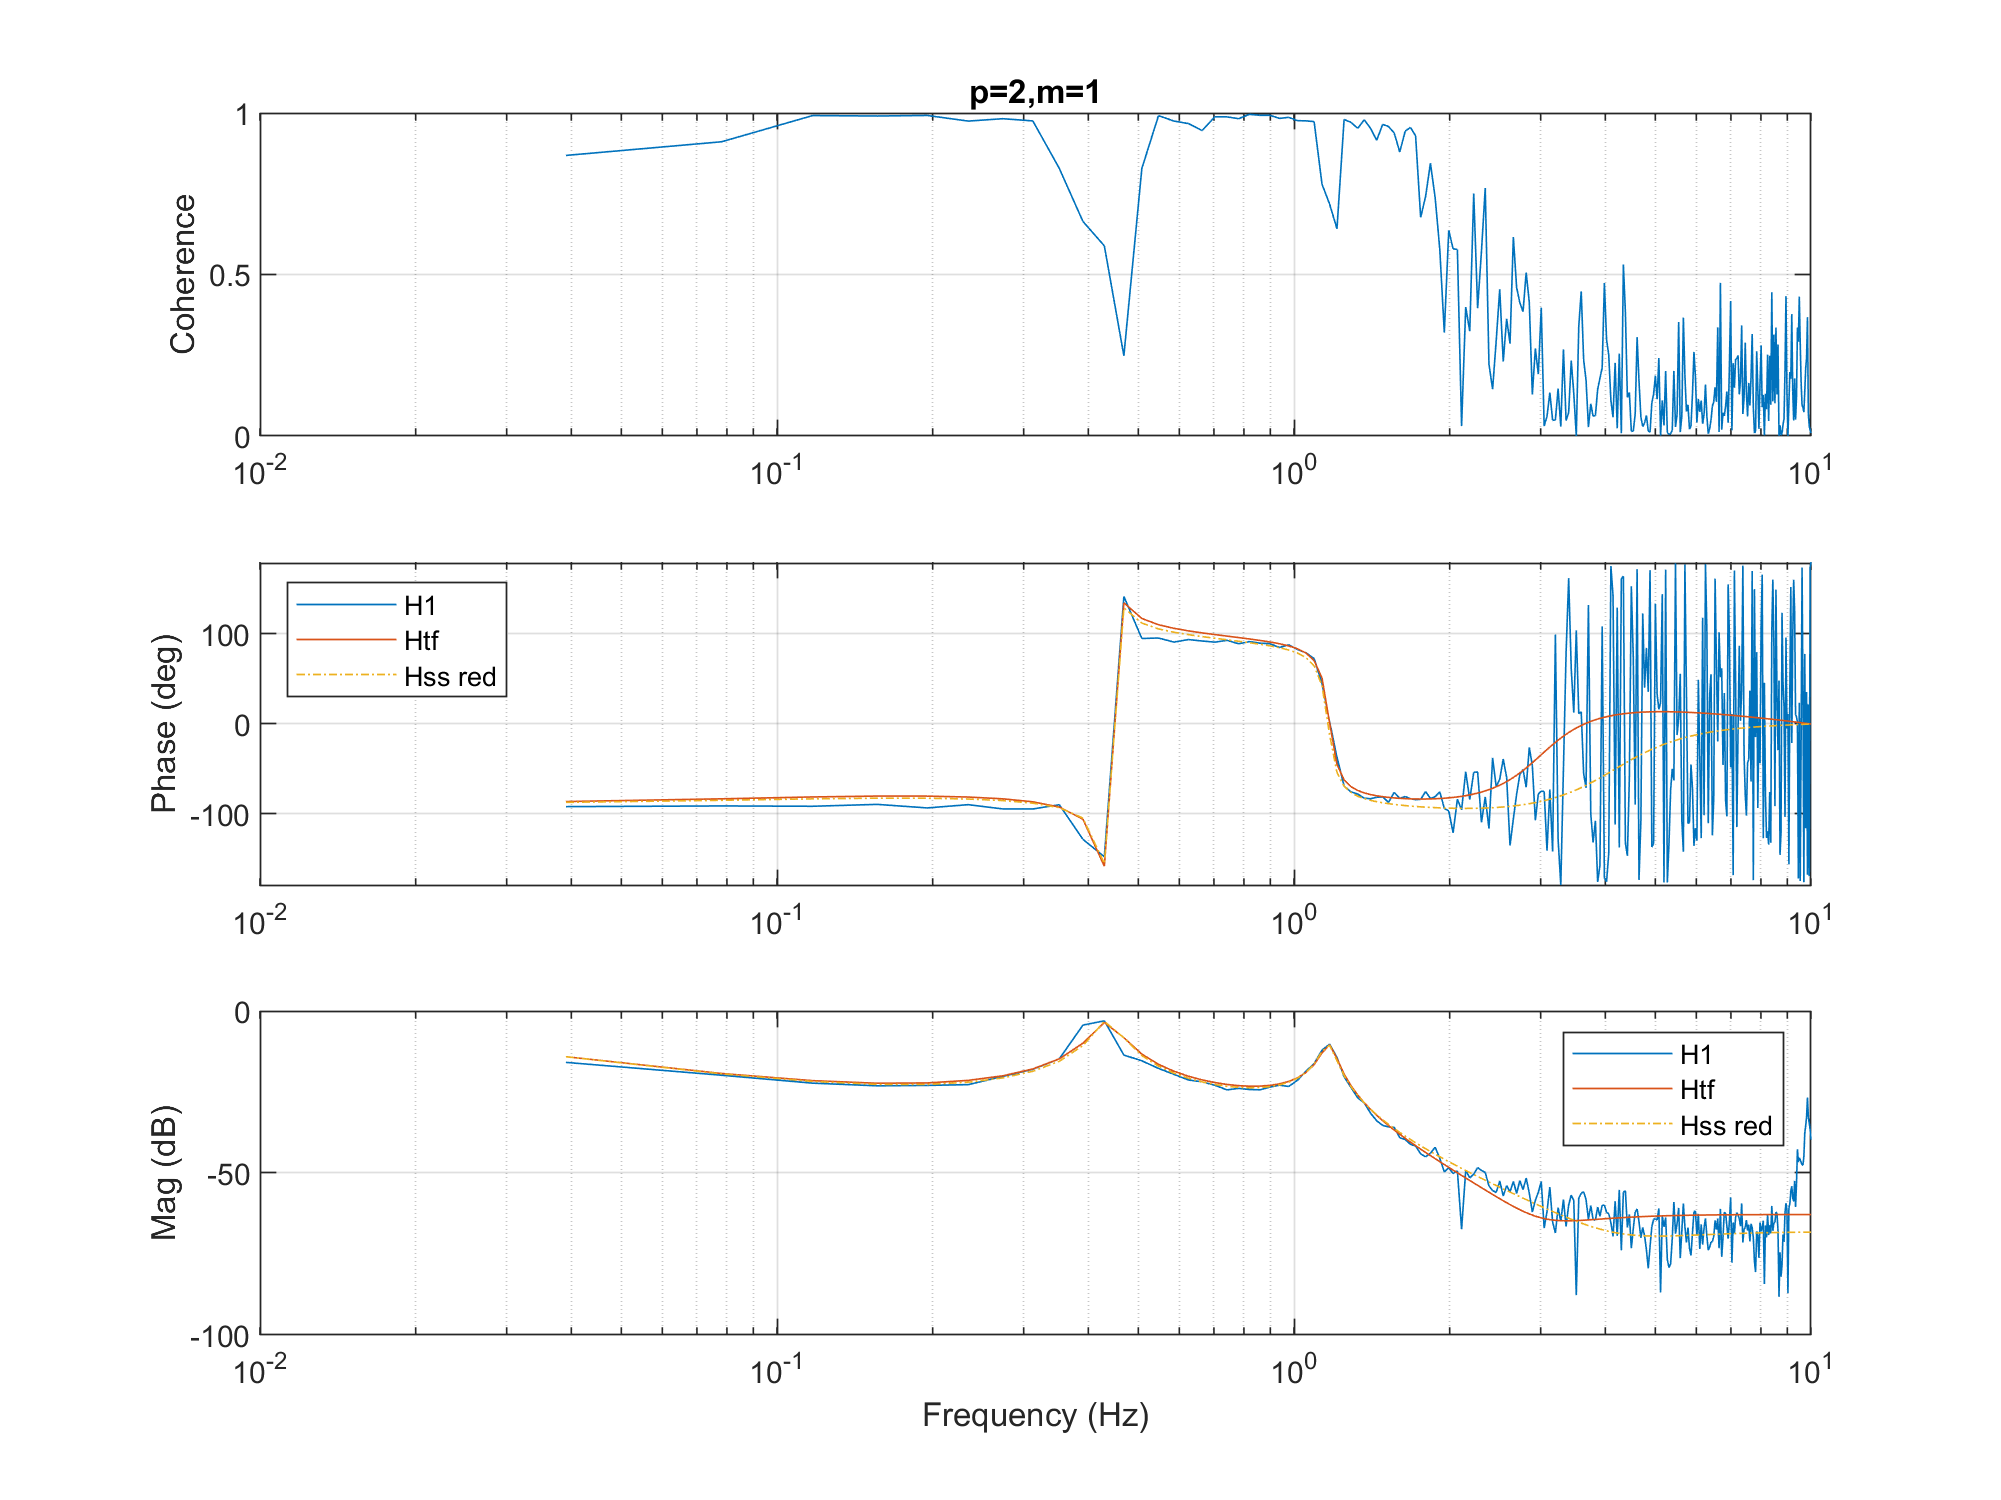

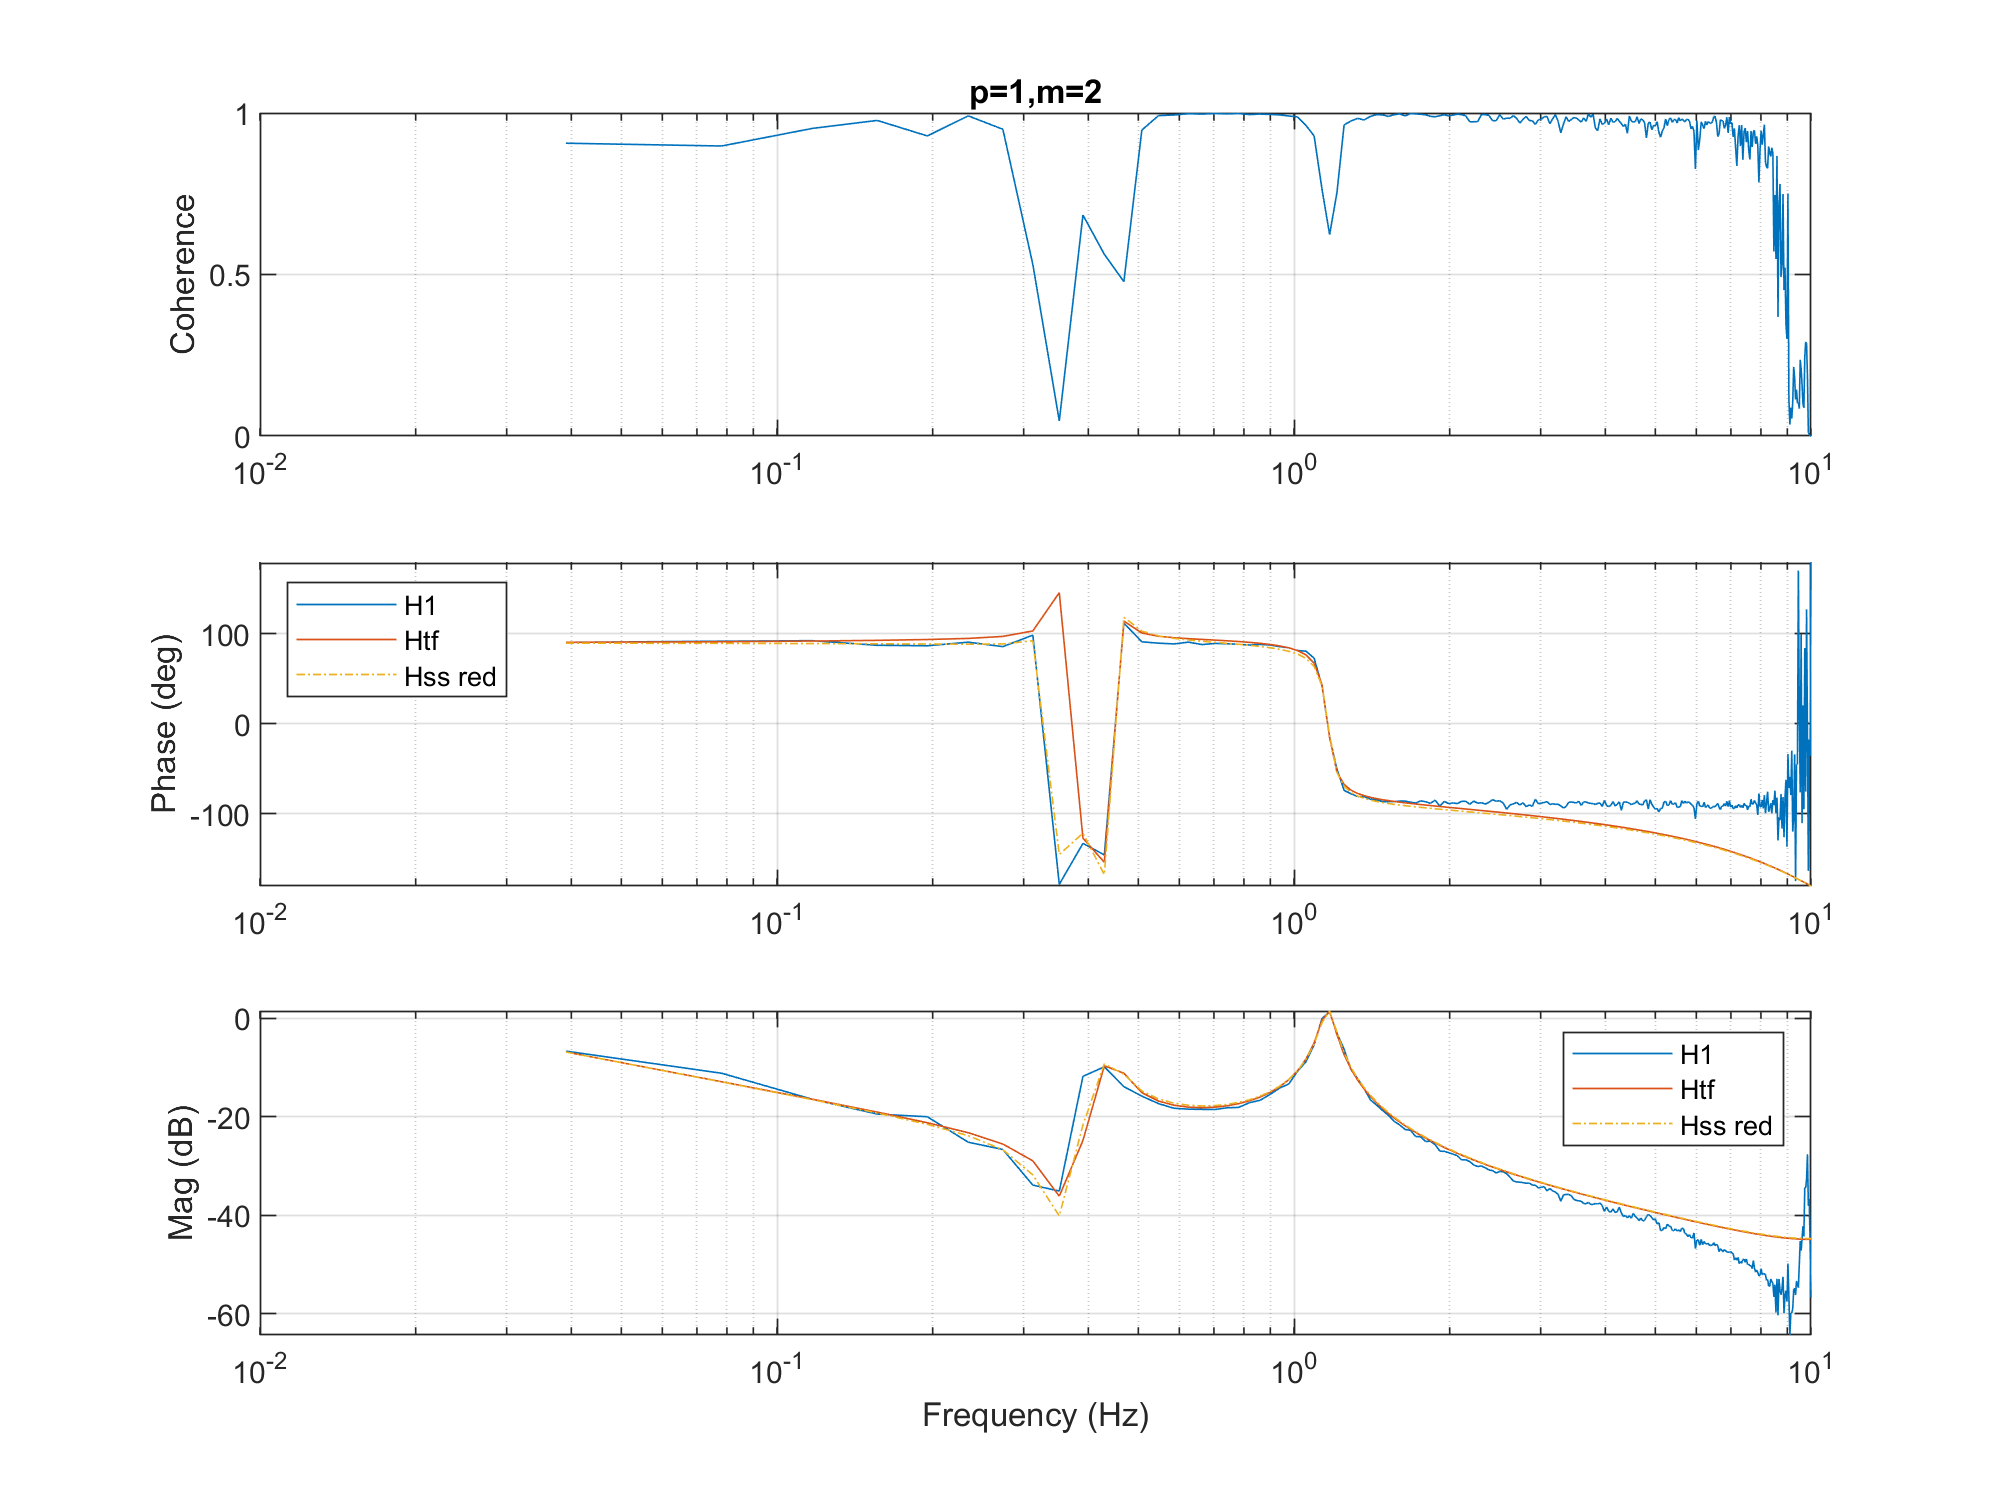

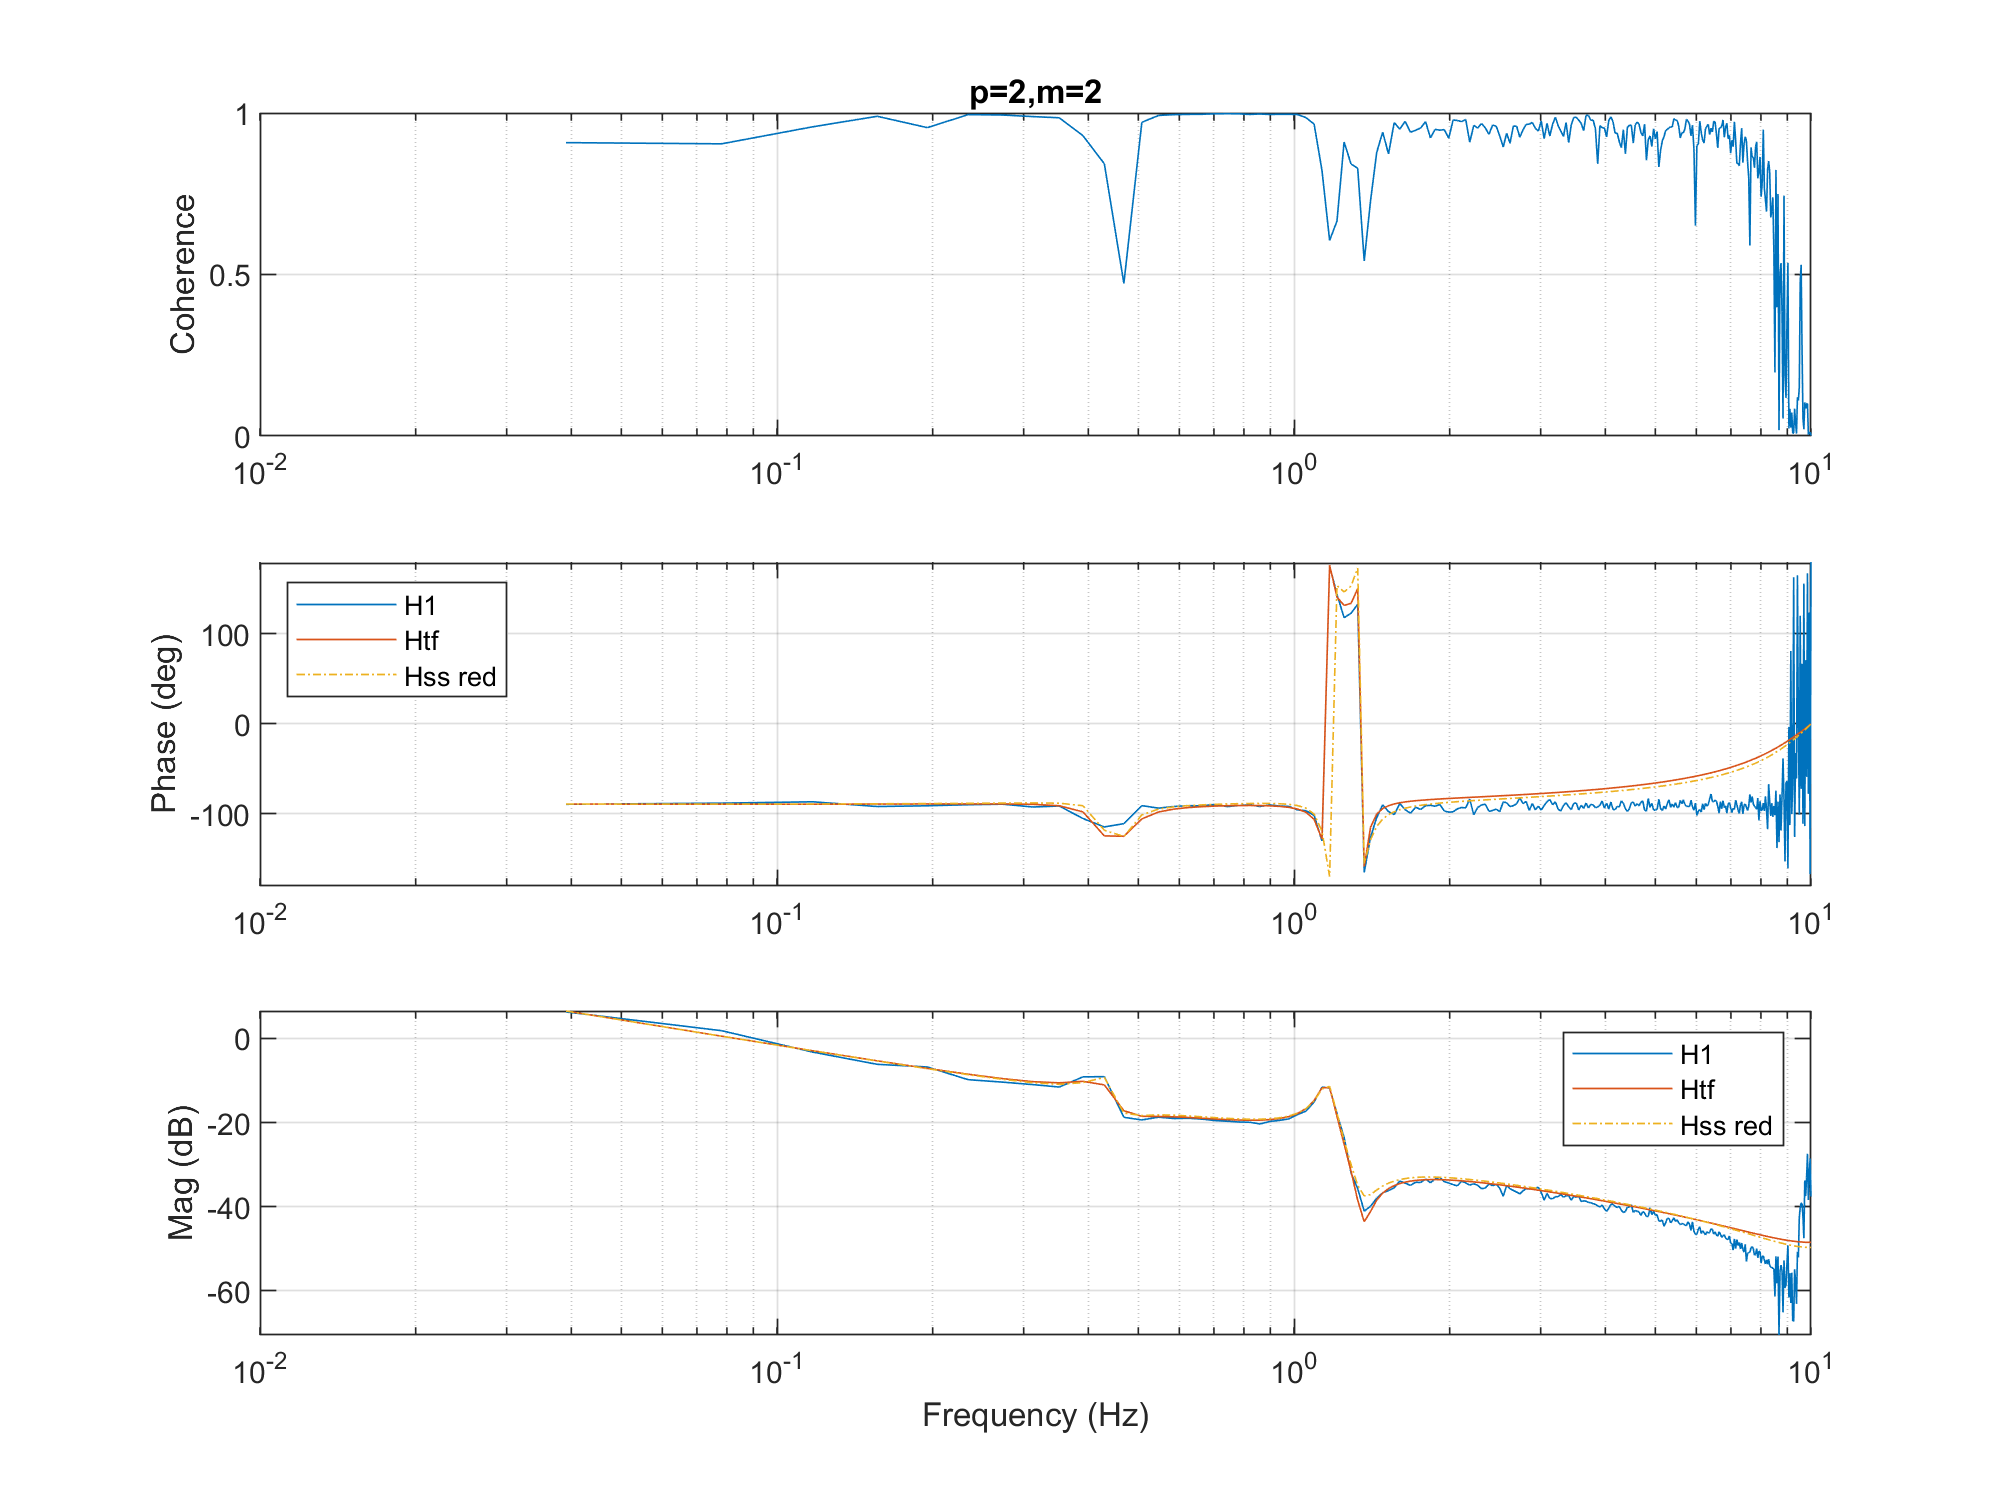

for m = 1:2
    for p = 1:2
        Name_str = sprintf('p=%d,m=%d',p,m);
        
        Ph_H1(p,m,:) = (180/pi)*angle(H1(p,m,:));
        Mag_H1(p,m,:) = 20*log10(abs(H1(p,m,:)));
        
        figure

        set(gca,'fontsize',14) 
        set(gcf,'Position',[0 0 800 600])
        subplot(3,1,1)     
        semilogx(fr,squeeze(gamma(p,m,:)))
        grid on
        ylabel('Coherence')
        title(Name_str,'FontSize',30)
        subplot(3,1,2)
        semilogx(fr,squeeze(Ph_H1(p,m,:)),fr,squeeze(Ph_tf(p,m,:)),fr,squeeze(Ph_red(p,m,:)),'-.');
        legend('H1','Htf','Hss red','Location','northwest')
        ylabel('Phase (deg)')
        ylim([-180 180])
        grid on
        subplot(3,1,3)
        semilogx(fr,squeeze(Mag_H1(p,m,:)),fr,squeeze(Mag_tf(p,m,:)),fr,squeeze(Mag_red(p,m,:)),'-.');
        ylabel('Mag (dB)')
        xlabel('Frequency (Hz)')
        legend('H1','Htf','Hss red','Location','northeast')
        grid on
    end
end